clear all;
%close all;

Define sample time

Discretzie steer angle;

dt= 0.01; % stepwise
t_list= (0:dt:5)'; % total time
u_steer_dis= deg2rad((-15:1.5:15)');
state_passed= [];
path_index_list=[];
d_paths_max_list=[];
index_list=[];

path_opt_table= readtable('traj_opt.csv');

    
london_outer_table=readtable('london_outer.csv');

london_inner_table=readtable('london_inner.csv');


path_opt_xy= [path_opt_table.x_Traj_x, path_opt_table.traj_y];

Initilize the states;

Call StateUpdate function to calcuate the path for each steer inputs

state0= [-0.08855;0.8886;0;0.01];
v_last_iter=0;

for iter=1:100
    [state, u_tmp] = StateUpdate_dt(state0, u_steer_dis, t_list, dt, v_last_iter);


 end points of each path

    paths_end=[];
    for j= 1:length(t_list):length(state)
        paths_end= [paths_end; [state(1, j+length(t_list)-1), state(2, j+length(t_list)-1)]];
    end


calculate length of each path

    d_path_norm=[];
    for i= 1: length(paths_end)
        d= norm([paths_end(i,1)-path_opt_xy(1,1), paths_end(i,2)-path_opt_xy(1,2), 2]);
        d_path_norm= [d_path_norm;d];
    end
    
    d_paths_max= max(d_path_norm);
    
    d_paths_max_list= [d_paths_max_list; d_paths_max];

Find the index of point which is closest to the end states

    d_path_opt=0;
    k=1;
    
    while(d_path_opt<d_paths_max)
        d_path_opt= norm([path_opt_xy(k,1)- path_opt_xy(1,1), path_opt_xy(k,2)- path_opt_xy(1,2)],2);
        k=k+1;
    end
    
    index=k-1;
    index_list=[index_list; index];

find the index of path

    paths_history=[];
    d_sum_list=[];
    
    for j= 1:length(t_list):length(state)
        d_sum= 0;
        paths_tmp=[state(1,j:j+length(t_list)-1)',state(2,j:j+length(t_list)-1)'];
        for k= 1:length(paths_tmp)
            dx= paths_tmp(k,1)- path_opt_xy(index,1);
            dy= paths_tmp(k,2)- path_opt_xy(index,2);
            d_tmp= norm([dx,dy],2);
            d_sum= d_sum+ d_tmp;
        end
        d_sum_list= [d_sum_list; d_sum];
        paths_history= [paths_history; paths_tmp];
    end
    
    path_index= find(d_sum_list==(min(d_sum_list)));
  
    path_index_list=[path_index_list; path_index];

    m= 1:length(t_list):length(state);
    j= m(path_index);
    state_select= state(1:4,j:j+length(t_list)-1);
    state_next= state_select(1:4,end);
    state_passed= [state_passed, state_next];
    v_last_iter= state0(4);
    state0= state_next;
end

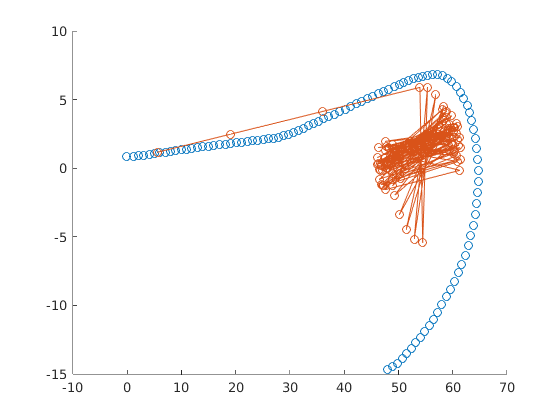

close all;
plot_num= 1:100;
figure()
scatter(path_opt_table.x_Traj_x(plot_num), path_opt_table.traj_y(plot_num));
hold on;
plot(state_passed(1,:),state_passed(2,:), 'o-');

% paths_end=[];
% for j= 1:length(t_list):length(state)
%     plot(state(1,j:j+length(t_list)-1), state(2,j:j+length(t_list)-1), 'color', 'red');
%     hold on;
%     scatter(state(1, j+length(t_list)-1), state(2,j+length(t_list)-1), 'x');
%     hold on;
%
%     paths_end= [paths_end; [state(1, j+length(t_list)-1), state(2, j+length(t_list)-1)]];
% end